clc; clear; close all;

%% INPUT GAMBAR
[file, path] = uigetfile({'*.jpg;*.png;*.jpeg'}, 'Select Image');

if isequal(file,0)
    disp('No image selected');
    return;
end

img = imread(fullfile(path,file));

if size(img,3) == 3
    gray = rgb2gray(img);
else
    gray = img;
end

%% GABOR FILTER BANK
wavelength = [4 8 16];
orientation = 0:45:135;

gaborArray = gabor(wavelength, orientation);

fprintf('Jumlah Gabor Filter: %d\n', length(gaborArray));

Jumlah Gabor Filter: 12


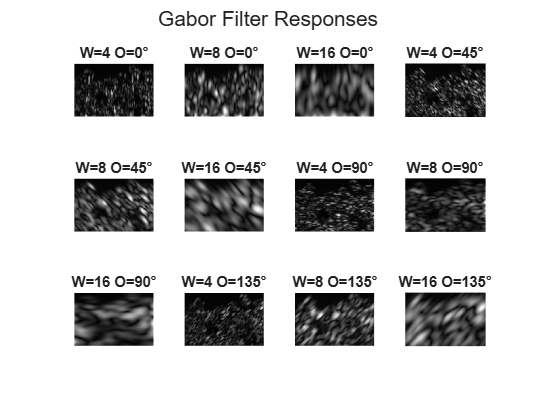


%% EKSTRAKSI FITUR GABOR
gaborMag = imgaborfilt(gray, gaborArray);

%% VISUALISASI RESPON GABOR
figure('Name','Gabor Feature Maps');

for i = 1:length(gaborArray)

    subplot(length(wavelength), length(orientation), i);

    imshow(gaborMag(:,:,i), []);

    title(sprintf('W=%d O=%d°', ...
        gaborArray(i).Wavelength, ...
        round(gaborArray(i).Orientation)));

end

sgtitle('Gabor Filter Responses');

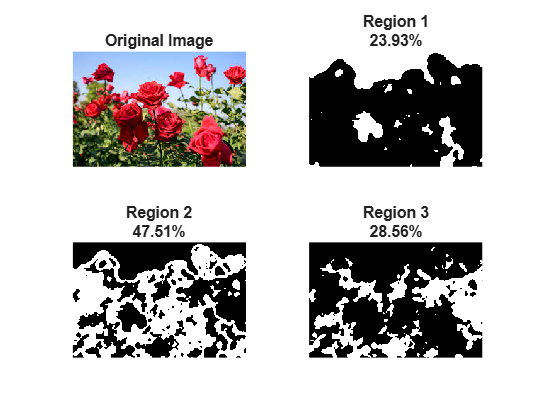


%% FEATURE MATRIX
[nrows,ncols] = size(gray);

numFilters = length(gaborArray);

features = zeros(nrows*ncols, numFilters);

for i = 1:numFilters
    features(:,i) = reshape(gaborMag(:,:,i), [], 1);
end

features = normalize(features);

%% K-MEANS CLUSTERING (K-MEANS++)
k = 3;

[idx,C] = kmeans(features,...
                 k,...
                 'Start','plus',...
                 'MaxIter',300,...
                 'Replicates',5);

segmented = reshape(idx,nrows,ncols);

%% HITUNG PERSENTASE AREA
totalPixels = numel(segmented);

regionPercent = zeros(k,1);

regionPixels = zeros(k,1);

for i = 1:k

    regionPixels(i) = sum(segmented(:)==i);

    regionPercent(i) = ...
        (regionPixels(i)/totalPixels)*100;

end

%% VISUALISASI REGION
figure('Name','Segmentation Results');

totalPlot = k + 1;

rows = ceil(sqrt(totalPlot));
cols = ceil(totalPlot/rows);

subplot(rows,cols,1);
imshow(img);
title('Original Image');

for i = 1:k

    subplot(rows,cols,i+1);

    mask = segmented == i;

    imshow(mask);

    title(sprintf('Region %d\n%.2f%%', ...
          i, regionPercent(i)));

end

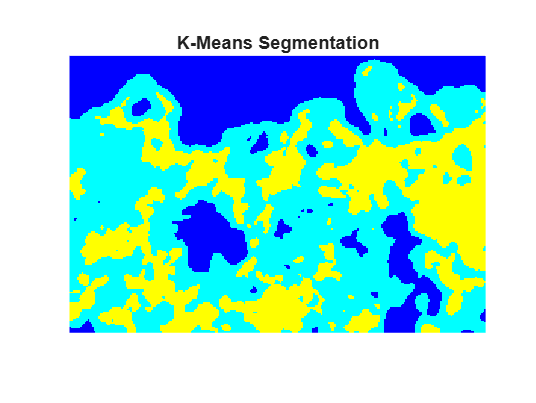


%% SEGMENTASI BERWARNA
coloredSeg = label2rgb(segmented);

figure('Name','Colored Segmentation');
imshow(coloredSeg);
title('K-Means Segmentation');

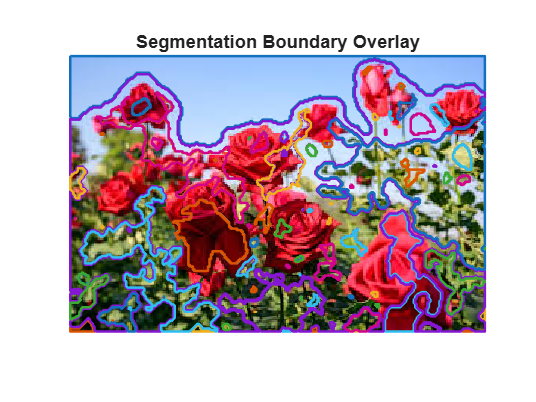


%% OVERLAY PADA GAMBAR ASLI
figure('Name','Overlay Segmentation');

imshow(img);
hold on

for i = 1:k

    boundaries = bwboundaries(segmented == i);

    for j = 1:length(boundaries)

        boundary = boundaries{j};

        plot(boundary(:,2),...
             boundary(:,1),...
             'LineWidth',1.5);

    end

end

title('Segmentation Boundary Overlay');

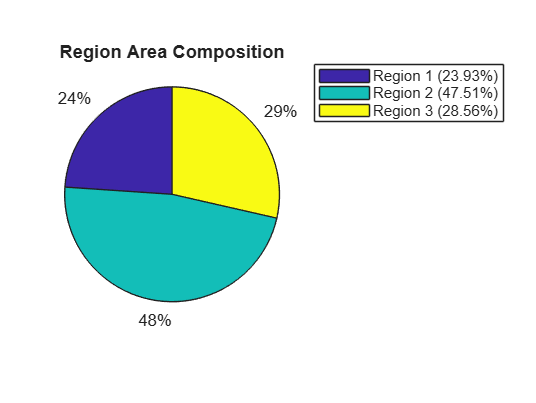


%% PIE CHART KOMPOSISI AREA
figure('Name','Area Composition');

pie(regionPercent);

labels = strings(k,1);

for i = 1:k
    labels(i) = sprintf('Region %d (%.2f%%)',...
                        i,...
                        regionPercent(i));
end

legend(labels,'Location','bestoutside');

title('Region Area Composition');

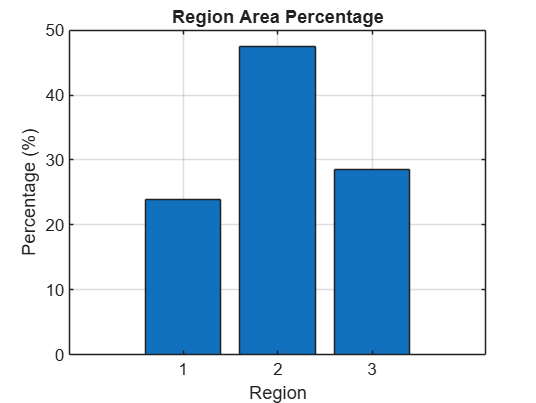


%% BAR CHART
figure('Name','Region Comparison');

bar(regionPercent);

xlabel('Region');
ylabel('Percentage (%)');
title('Region Area Percentage');
grid on;


%% ANALISIS REGION
disp(' ');

disp('===== REGION ANALYSIS =====');

===== REGION ANALYSIS =====



for i = 1:k

    fprintf('\nRegion %d\n',i);

    fprintf('Pixels      : %d\n', ...
        regionPixels(i));

    fprintf('Percentage  : %.2f%%\n', ...
        regionPercent(i));

end


Region 1


Pixels      : 12042


Percentage  : 23.93%



Region 2


Pixels      : 23908


Percentage  : 47.51%



Region 3


Pixels      : 14375


Percentage  : 28.56%



%% SIMPAN HASIL
[~, namaFile, ~] = fileparts(file);

namaHasil = ['hasil_segmentasi_' namaFile '.png'];

imwrite(coloredSeg, namaHasil);

disp(' ');

disp('Hasil segmentasi disimpan sebagai:');

Hasil segmentasi disimpan sebagai:


disp(namaHasil);

hasil_segmentasi_download (8).png
